clc;
clear;
close all;

%% ========================================================
% STEP 4: VISUAL-INERTIAL STATE ESTIMATION
% Error-State Kalman Filter
%
% INPUTS FROM STEP 3:
%   t
%   dt
%   pd, vd, ad
%   p_true, v_true, a_true
%   p_camera
%   a_imu
%   omega_imu
%
% OUTPUTS FOR STEP 5:
%   p_est_history
%   v_est_history
%   R_est_history
%   omega_est_history
%   ba_est_history
%   bg_est_history
% ========================================================

open("drone_toy_model.mat")

ans = struct with fields:
              R_camera: [3×3×1001 double]
                R_true: [3×3×1001 double]
                 a_imu: [1001×3 double]
                a_true: [1001×3 double]
            accel_bias: [0.0200 -0.0100 0.0300]
                    ad: [1001×3 double]
                    dt: 0.0100
             gyro_bias: [0.0050 -0.0030 0.0020]
             omega_imu: [1001×3 double]
            omega_true: [1001×3 double]
              p_camera: [1001×3 double]
                p_true: [1001×3 double]
                    pd: [1001×3 double]
    sigma_acceleration: 0.1000
    sigma_camera_angle: 0.0175
            sigma_gyro: 0.0100
        sigma_position: 0.0500
                     t: [1001×1 double]
                v_true: [1001×3 double]
                    vd: [1001×3 double]
          waypointTime: [6×1 double]
             waypoints: [6×3 double]


load('drone_toy_model.mat');

%% --------------------------------------------------------
% 1. Check that required Step 3 data exists
% ---------------------------------------------------------

requiredVariables = {
    't'
    'dt'
    'pd'
    'vd'
    'ad'
    'p_true'
    'v_true'
    'a_true'
    'p_camera'
    'a_imu'
    'omega_imu'
    'R_camera'
};

for i = 1:length(requiredVariables)

    if ~exist(requiredVariables{i},'var')

        error(['Missing variable: ', ...
               requiredVariables{i}, ...
               '. Update Step 3 so it saves this variable ', ...
               'to drone_toy_model.mat.']);

    end

end

numSamples = length(t);

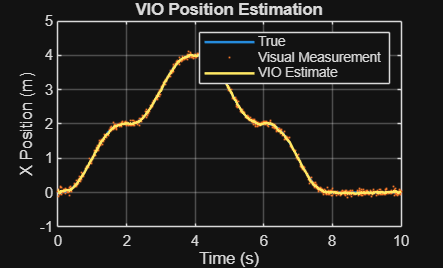


%% --------------------------------------------------------
% 2. True state
%
% These are ONLY used for evaluation.
% They are NOT given to the estimator.
% ---------------------------------------------------------

p_true = pd;
v_true = vd;
a_true = ad;

%% --------------------------------------------------------
% 3. Gravity
% ---------------------------------------------------------

g = [0; 0; -9.81];

%% --------------------------------------------------------
% 4. True attitude for evaluation
%
% This reconstructs the ground-truth attitude associated
% with the reference trajectory.
%
% IMPORTANT:
% R_true is NOT used by the estimator.
% It is only used after estimation to calculate error.
% ---------------------------------------------------------

R_true = zeros(3,3,numSamples);

for k = 1:numSamples

    %% Desired yaw

    if norm(v_true(k,1:2)) > 1e-4

        yaw = ...
            atan2(v_true(k,2), ...
                  v_true(k,1));

    else

        yaw = 0;

    end

    %% Approximate pitch and roll

    pitch = ...
        atan2(a_true(k,1),9.81);

    roll = ...
        -atan2(a_true(k,2),9.81);

    %% Rotation about X

    Rx = [
        1 0 0;
        0 cos(roll) -sin(roll);
        0 sin(roll) cos(roll)
    ];

    %% Rotation about Y

    Ry = [
        cos(pitch) 0 sin(pitch);
        0 1 0;
        -sin(pitch) 0 cos(pitch)
    ];

    %% Rotation about Z

    Rz = [
        cos(yaw) -sin(yaw) 0;
        sin(yaw) cos(yaw) 0;
        0 0 1
    ];

    %% Body-to-world rotation

    R_true(:,:,k) = ...
        Rz * Ry * Rx;

end

%% --------------------------------------------------------
% 5. Sensor parameters
%
% These values describe the measurements generated in
% Step 3.
% ---------------------------------------------------------

sigma_visual_position = 0.05;

sigma_visual_angle = deg2rad(1.0);

%% --------------------------------------------------------
% 6. Initial nominal state
%
% The estimator starts from the first visual measurement.
% It does NOT use p_true or R_true for initialization.
% ---------------------------------------------------------

p_est = ...
    p_camera(1,:)';

v_est = zeros(3,1);

R_est = ...
    R_camera(:,:,1);

ba_est = zeros(3,1);

bg_est = zeros(3,1);

%% --------------------------------------------------------
% 7. Error-state covariance
%
% Error state:
%
% delta_x =
%
% [ delta_p
%   delta_v
%   delta_theta
%   delta_ba
%   delta_bg ]
%
% Total dimension = 15
% ---------------------------------------------------------

P_cov = ...
    eye(15) * 0.01;

%% --------------------------------------------------------
% 8. Visual measurement covariance
%
% Measurement:
%
% z =
% [ position
%   attitude ]
%
% Dimension = 6
% ---------------------------------------------------------

R_visual = diag([
    sigma_visual_position^2
    sigma_visual_position^2
    sigma_visual_position^2
    sigma_visual_angle^2
    sigma_visual_angle^2
    sigma_visual_angle^2
]);

%% --------------------------------------------------------
% 9. Process noise covariance
% ---------------------------------------------------------

Q = zeros(15);

Q(1:3,1:3) = ...
    1e-5 * eye(3);

Q(4:6,4:6) = ...
    1e-3 * eye(3);

Q(7:9,7:9) = ...
    1e-4 * eye(3);

Q(10:12,10:12) = ...
    1e-6 * eye(3);

Q(13:15,13:15) = ...
    1e-6 * eye(3);

%% --------------------------------------------------------
% 10. Storage
% ---------------------------------------------------------

p_est_history = ...
    zeros(numSamples,3);

v_est_history = ...
    zeros(numSamples,3);

R_est_history = ...
    zeros(3,3,numSamples);

omega_est_history = ...
    zeros(numSamples,3);

ba_est_history = ...
    zeros(numSamples,3);

bg_est_history = ...
    zeros(numSamples,3);

%% --------------------------------------------------------
% 11. Error-State Kalman Filter
% ---------------------------------------------------------

for k = 1:numSamples

    %% ====================================================
    % A. Correct IMU measurements using estimated biases
    % ====================================================

    a_corrected = ...
        a_imu(k,:)' - ba_est;

    omega_corrected = ...
        omega_imu(k,:)' - bg_est;

    %% ====================================================
    % B. IMU state propagation
    % ====================================================

    if k > 1

        %% Position

        p_est = ...
            p_est ...
            + v_est*dt ...
            + 0.5 * ...
            (R_est*a_corrected + g) * dt^2;

        %% Velocity

        v_est = ...
            v_est ...
            + (R_est*a_corrected + g)*dt;

        %% Orientation
        %
        % R(k+1) =
        % R(k) Exp([omega]x dt)
        %

        R_est = ...
            R_est * ...
            expm(skew(omega_corrected*dt));

        %% Force R back onto SO(3)

        [U,~,V] = svd(R_est);

        R_est = U*V';

        if det(R_est) < 0

            U(:,3) = -U(:,3);

            R_est = U*V';

        end

    end

    %% ====================================================
    % C. Error-state transition matrix
    % ====================================================

    F = eye(15);

    %% Position error depends on velocity error

    F(1:3,4:6) = ...
        eye(3)*dt;

    %% Velocity error due to attitude error

    F(4:6,7:9) = ...
        -R_est * ...
        skew(a_corrected) * dt;

    %% Velocity error due to accelerometer bias

    F(4:6,10:12) = ...
        -R_est * dt;

    %% Attitude error propagation

    F(7:9,7:9) = ...
        expm(-skew(omega_corrected*dt));

    %% Attitude error due to gyro bias

    F(7:9,13:15) = ...
        -eye(3)*dt;

    %% ====================================================
    % D. Covariance propagation
    % ====================================================

    P_cov = ...
        F * P_cov * F' + Q;

    %% ====================================================
    % E. Visual position innovation
    % ====================================================

    z_position = ...
        p_camera(k,:)';

    position_innovation = ...
        z_position - p_est;

    %% ====================================================
    % F. Visual attitude innovation
    %
    % Right attitude error:
    %
    % delta_theta =
    % Log( R_est' R_visual )
    % ====================================================

    R_visual_k = ...
        R_camera(:,:,k);

    R_error = ...
        R_est' * R_visual_k;

    delta_theta = ...
        logSO3(R_error);

    %% ====================================================
    % G. Combined visual innovation
    % ====================================================

    innovation = [
        position_innovation;
        delta_theta
    ];

    %% ====================================================
    % H. Measurement matrix
    %
    % Position measurement observes delta_p.
    %
    % Attitude measurement observes delta_theta.
    % ====================================================

    H = zeros(6,15);

    H(1:3,1:3) = ...
        eye(3);

    H(4:6,7:9) = ...
        eye(3);

    %% ====================================================
    % I. Innovation covariance
    % ====================================================

    S = ...
        H * P_cov * H' + R_visual;

    %% ====================================================
    % J. Kalman gain
    % ====================================================

    K = ...
        P_cov * H' / S;

    %% ====================================================
    % K. Estimate error state
    % ====================================================

    delta_x = ...
        K * innovation;

    %% ====================================================
    % L. Inject error into nominal state
    % ====================================================

    %% Position

    p_est = ...
        p_est + delta_x(1:3);

    %% Velocity

    v_est = ...
        v_est + delta_x(4:6);

    %% Attitude

    R_est = ...
        R_est * ...
        expm(skew(delta_x(7:9)));

    %% Accelerometer bias

    ba_est = ...
        ba_est + delta_x(10:12);

    %% Gyroscope bias

    bg_est = ...
        bg_est + delta_x(13:15);

    %% Ensure attitude remains in SO(3)

    [U,~,V] = svd(R_est);

    R_est = U*V';

    if det(R_est) < 0

        U(:,3) = -U(:,3);

        R_est = U*V';

    end

    %% ====================================================
    % M. Joseph-form covariance update
    %
    % More numerically stable than:
    %
    % P = (I-KH)P
    % ====================================================

    I_KH = ...
        eye(15) - K*H;

    P_cov = ...
        I_KH * P_cov * I_KH' ...
        + K * R_visual * K';

    %% ====================================================
    % N. Store estimated state
    % ====================================================

    p_est_history(k,:) = ...
        p_est';

    v_est_history(k,:) = ...
        v_est';

    R_est_history(:,:,k) = ...
        R_est;

    omega_est_history(k,:) = ...
        omega_corrected';

    ba_est_history(k,:) = ...
        ba_est';

    bg_est_history(k,:) = ...
        bg_est';

end

%% ========================================================
% 12. Estimation errors
% =========================================================

position_error = ...
    p_est_history - p_true;

velocity_error = ...
    v_est_history - v_true;

position_RMSE = ...
    sqrt(mean(position_error.^2,1));

velocity_RMSE = ...
    sqrt(mean(velocity_error.^2,1));

%% ========================================================
% 13. Attitude estimation error
% =========================================================

attitude_error = ...
    zeros(numSamples,1);

for k = 1:numSamples

    R_error = ...
        R_true(:,:,k)' * ...
        R_est_history(:,:,k);

    theta_error = ...
        logSO3(R_error);

    attitude_error(k) = ...
        norm(theta_error);

end

attitude_RMSE = ...
    sqrt(mean(attitude_error.^2));

%% ========================================================
% 14. SO(3) validity checks
% =========================================================

rotation_orthogonality_error = ...
    zeros(numSamples,1);

rotation_determinant_error = ...
    zeros(numSamples,1);

for k = 1:numSamples

    Rk = ...
        R_est_history(:,:,k);

    rotation_orthogonality_error(k) = ...
        norm(Rk'*Rk - eye(3),'fro');

    rotation_determinant_error(k) = ...
        abs(det(Rk)-1);

end

%% ========================================================
% 15. Plot X position
% =========================================================

figure;

plot(t,p_true(:,1), ...
     'LineWidth',1.5);

hold on;

plot(t,p_camera(:,1), ...
     '.', ...
     'MarkerSize',3);

plot(t,p_est_history(:,1), ...
     'LineWidth',1.5);

xlabel('Time (s)');
ylabel('X Position (m)');

title('VIO Position Estimation');

legend( ...
    'True', ...
    'Visual Measurement', ...
    'VIO Estimate');

grid on;

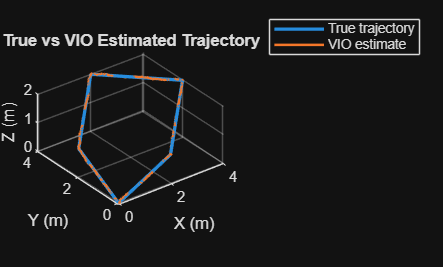


%% ========================================================
% 16. Plot 3D trajectory
% =========================================================

figure;

plot3( ...
    p_true(:,1), ...
    p_true(:,2), ...
    p_true(:,3), ...
    'LineWidth',2);

hold on;

plot3( ...
    p_est_history(:,1), ...
    p_est_history(:,2), ...
    p_est_history(:,3), ...
    'LineWidth',1.5);

grid on;
axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('True vs VIO Estimated Trajectory');

legend( ...
    'True trajectory', ...
    'VIO estimate');

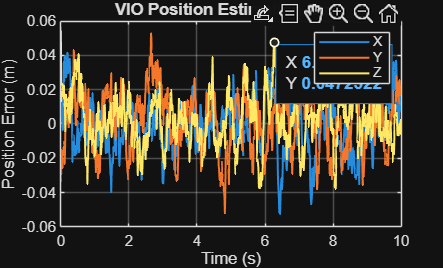


%% ========================================================
% 17. Plot position error
% =========================================================

figure;

plot( ...
    t, ...
    position_error(:,1), ...
    'LineWidth',1.2);

hold on;

plot( ...
    t, ...
    position_error(:,2), ...
    'LineWidth',1.2);

plot( ...
    t, ...
    position_error(:,3), ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('Position Error (m)');

title('VIO Position Estimation Error');

legend('X','Y','Z');

grid on;

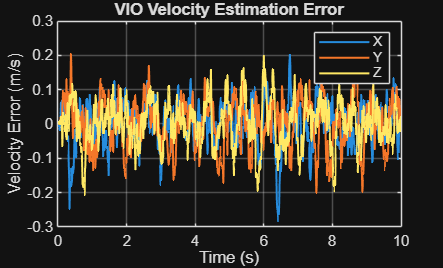


%% ========================================================
% 18. Plot velocity error
% =========================================================

figure;

plot( ...
    t, ...
    velocity_error(:,1), ...
    'LineWidth',1.2);

hold on;

plot( ...
    t, ...
    velocity_error(:,2), ...
    'LineWidth',1.2);

plot( ...
    t, ...
    velocity_error(:,3), ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('Velocity Error (m/s)');

title('VIO Velocity Estimation Error');

legend('X','Y','Z');

grid on;

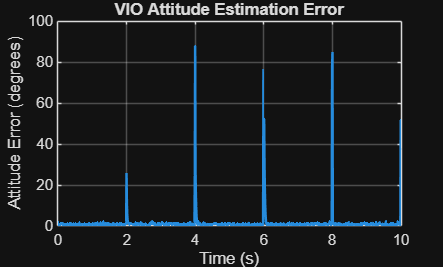


%% ========================================================
% 19. Plot attitude error
% =========================================================

figure;

plot( ...
    t, ...
    rad2deg(attitude_error), ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('Attitude Error (degrees)');

title('VIO Attitude Estimation Error');

grid on;


%% ========================================================
% 20. Display results
% =========================================================

fprintf('\n');
fprintf('========================================\n');

fprintf('VISUAL-INERTIAL ESTIMATION RESULTS\n');

VISUAL-INERTIAL ESTIMATION RESULTS


fprintf('========================================\n');


fprintf('\nPosition RMSE:\n');


Position RMSE:



fprintf('X = %.4f m\n', ...
    position_RMSE(1));

X = 0.0154 m



fprintf('Y = %.4f m\n', ...
    position_RMSE(2));

Y = 0.0168 m



fprintf('Z = %.4f m\n', ...
    position_RMSE(3));

Z = 0.0148 m



fprintf('\nVelocity RMSE:\n');


Velocity RMSE:



fprintf('X = %.4f m/s\n', ...
    velocity_RMSE(1));

X = 0.0644 m/s



fprintf('Y = %.4f m/s\n', ...
    velocity_RMSE(2));

Y = 0.0700 m/s



fprintf('Z = %.4f m/s\n', ...
    velocity_RMSE(3));

Z = 0.0643 m/s



fprintf('\nAttitude RMSE = %.4f degrees\n', ...
    rad2deg(attitude_RMSE));


Attitude RMSE = 6.2666 degrees



fprintf('\nFinal accelerometer bias estimate:\n');


Final accelerometer bias estimate:



disp(ba_est');

    0.0109   -0.0048    0.0191




fprintf('Final gyroscope bias estimate:\n');

Final gyroscope bias estimate:



disp(bg_est');

    0.0089   -0.0029    0.1333




fprintf('\nSO(3) validity:\n');


SO(3) validity:



fprintf( ...
    'Maximum orthogonality error = %.4e\n', ...
    max(rotation_orthogonality_error));

Maximum orthogonality error = 1.7153e-15



fprintf( ...
    'Maximum determinant error = %.4e\n', ...
    max(rotation_determinant_error));

Maximum determinant error = 1.1102e-15



%% ========================================================
% 21. SAVE OUTPUTS FOR STEP 5
% =========================================================

save('drone_toy_model.mat', ...
     'waypoints', ...
     'waypointTime', ...
     't', ...
     'dt', ...
     'pd', ...
     'vd', ...
     'ad', ...
     'p_true', ...
     'v_true', ...
     'a_true', ...
     'p_camera', ...
     'R_camera',...
     'R_true',...
     'a_imu', ...
     'omega_true', ...
     'omega_imu', ...
     'p_est_history', ...
     'v_est_history', ...
     'R_est_history', ...
     'omega_est_history', ...
     'ba_est_history', ...
     'bg_est_history', ...
     'position_RMSE', ...
     'velocity_RMSE', ...
     'attitude_RMSE');

fprintf('\nStep 4 results saved to drone_toy_model.mat\n');


Step 4 results saved to drone_toy_model.mat



%% ========================================================
% LOCAL FUNCTIONS
% =========================================================

function S = skew(v)

    S = [
         0    -v(3)  v(2);
         v(3)  0    -v(1);
        -v(2) v(1)   0
    ];

end


function v = logSO3(R)

    %% Numerical protection

    cos_theta = ...
        (trace(R)-1)/2;

    cos_theta = ...
        max(-1,min(1,cos_theta));

    theta = ...
        acos(cos_theta);

    if theta < 1e-8

        v = zeros(3,1);

    else

        v = ...
            theta/(2*sin(theta)) * ...
            [
                R(3,2)-R(2,3);
                R(1,3)-R(3,1);
                R(2,1)-R(1,2)
            ];

    end

end

open("drone_toy_model.mat")

ans = struct with fields:
             R_camera: [3×3×1001 double]
        R_est_history: [3×3×1001 double]
               R_true: [3×3×1001 double]
                a_imu: [1001×3 double]
               a_true: [1001×3 double]
                   ad: [1001×3 double]
        attitude_RMSE: 0.1094
       ba_est_history: [1001×3 double]
       bg_est_history: [1001×3 double]
                   dt: 0.0100
    omega_est_history: [1001×3 double]
            omega_imu: [1001×3 double]
           omega_true: [1001×3 double]
             p_camera: [1001×3 double]
        p_est_history: [1001×3 double]
               p_true: [1001×3 double]
                   pd: [1001×3 double]
        position_RMSE: [0.0154 0.0168 0.0148]
                    t: [1001×1 double]
        v_est_history: [1001×3 double]
               v_true: [1001×3 double]
                   vd: [1001×3 double]
        velocity_RMSE: [0.0644 0.0700 0.0643]
         waypointTime: [6×1 double]
            waypoints: [6×3 double]


R_camera

R_camera = R_camera(:,:,1) =

    0.9998   -0.0152   -0.0128
    0.0148    0.9995   -0.0271
    0.0132    0.0269    0.9996


R_camera(:,:,2) =

    0.9998    0.0082    0.0192
   -0.0084    0.9999    0.0107
   -0.0191   -0.0109    0.9998


R_camera(:,:,3) =

    0.9975   -0.0266    0.0661
    0.0258    0.9996    0.0127
   -0.0664   -0.0109    0.9977


R_camera(:,:,4) =

    0.9995    0.0101    0.0286
   -0.0108    0.9996    0.0249
   -0.0284   -0.0252    0.9993


R_camera(:,:,5) =

    0.9958    0.0102    0.0914
   -0.0104    0.9999    0.0017
   -0.0913   -0.0027    0.9958


R_camera(:,:,6) =

    0.9980    0.0108    0.0625
   -0.0110    0.9999    0.0018
   -0.0625   -0.0025    0.9980


R_camera(:,:,7) =

    0.9974   -0.0066    0.0720
    0.0062    1.0000    0.0056
   -0.0720   -0.0051    0.9974


R_camera(:,:,8) =

    0.9941   -0.0241    0.1060
    0.0227    0.9996    0.0148
   -0.1063   -0.0123    0.9943


R_camera(:,:,9) =

    0.9928   -0.0096    0.1196
    0.0062    0.9996    0.0